# Linear Regression:

The data in the accompanying table relate heart rate at rest Y to kilograms body weight X.

X = [90, 86, 67, 89, 81, 75];
Y = [62, 45, 40, 55, 64, 53];

## A: Graph these data. Does it appear that there is a linear relationship between body weight and heart rate at rest?

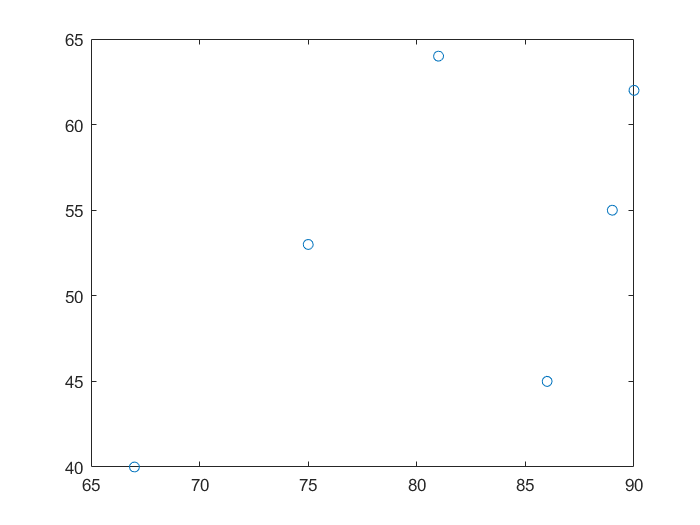


plot(X,Y, 'o')

R: Yes, a direct linear relationship.

## A: Compute a,b and write the regression equation for these data. Plot the regression line on the graph. Interpret the estimated regressin coefficients.

new_X = [ones(1,size(X,2)); X]'

new_X =      1    90
     1    86
     1    67
     1    89
     1    81
     1    75


theta = pinv(new_X' * new_X) *new_X' * Y'

theta =     4.7990
    0.5947


points = linspace(1,100,10);

prect = predict(points, theta);

J = cost_function(X, Y', theta);

J = 2.5461e-25

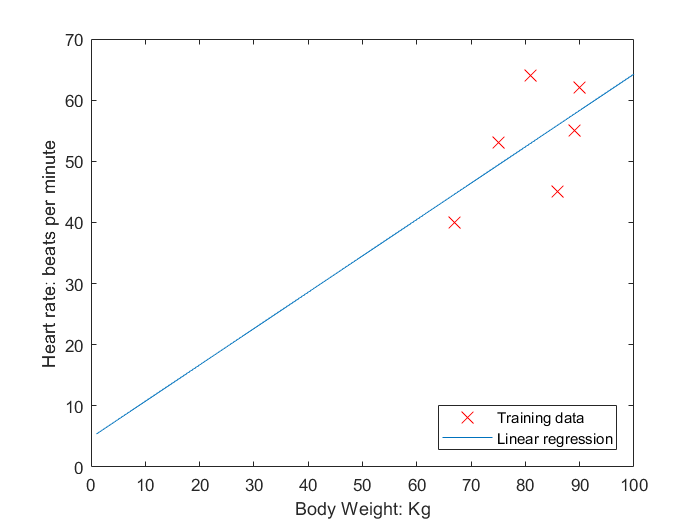


plot_data(X, Y);hold on
plot(points,rect, '-');hold off
legend('Training data', 'Linear regression', 'Location', 'southeast')